# **Welcome to Applied Statistics in MATLAB for Neuroscience!**

- Bridging theory and practice for neuroscience research.

- Focus on hands-on, applicable skills.

**Course Objectives**

- **Master MATLAB**: Efficiently analyze neuroscience data.

- **Apply Statistics**: Interpret key statistical principles in neuroimaging.

- **Cognitive Neuroscience Focus**: ERP, Time-Frequency, Connectivity.

** Why MATLAB for Neuroscience?**

- **Matrix-Based Computation**

- **Native Environment**: Designed for matrices and arrays.

- **Optimized Routines**: Fast, efficient operations (C/Fortran backend).

- **Relevance**: EEG/LFP are multi-dimensional arrays (Channels x Time x Trials), fitting MATLAB's strengths perfectly.

- **Extensive Built-in Toolboxes:**Signal Processing, Statistics & Machine Learning.

**Efficient Coding: Vectorization (**Speed Through Parallelism)

- **Definition**: Performing operations on entire arrays/matrices simultaneously, avoiding explicit loops.

- **Why it's Faster**: Leverages MATLAB's optimized, compiled internal routines. Reduces loop overhead.

Element-wise multiplication: `C = A .* B;` (vs. `for` loop).

clear;
clc;
warning('off', 'all');
N = 1e6; 
A = rand(1, N);
B = rand(1, N);

tic;
C_loop = zeros(1, N);
for i = 1:N
    C_loop(i) = A(i) * B(i);
end
fprintf('Loop execution time: %.4f seconds\n', toc);

Loop execution time: 0.0517 seconds



tic;
C_vec = A .* B; % Vectorized operation
fprintf('Vectorized execution time: %.4f seconds\n', toc);

Vectorized execution time: 0.0064 seconds


Summing rows: `sum(X, 2);` (vs. nested loops).

M = 1000; % Number of rows
P = 500;  % Number of columns
X = rand(M, P);

tic;
row_sums_loop = zeros(M, 1);
for i = 1:M
    for j = 1:P
        row_sums_loop(i) = row_sums_loop(i) + X(i, j);
    end
end
fprintf('Loop execution time (summing rows): %.4f seconds\n', toc);

Loop execution time (summing rows): 0.0196 seconds



tic;
row_sums_vec = sum(X, 2); % Vectorized operation
fprintf('Vectorized execution time (summing rows): %.4f seconds\n', toc);

Vectorized execution time (summing rows): 0.0090 seconds


Averaging trials: `mean(EEG_data, 3);` (vs. `for` loop).

% Assume EEG_data is [channels x time_points x trials]
num_channels = 64;
num_time_points = 1000;
num_trials = 200;
EEG_data = rand(num_channels, num_time_points, num_trials);

tic;
EEG_avg_loop = zeros(num_channels, num_time_points);
for c = 1:num_channels
    for t = 1:num_time_points
        current_sum = 0;
        for tr = 1:num_trials
            current_sum = current_sum + EEG_data(c, t, tr);
        end
        EEG_avg_loop(c, t) = current_sum / num_trials;
    end
end
fprintf('Loop execution time (averaging trials): %.4f seconds\n', toc);

Loop execution time (averaging trials): 0.2764 seconds



tic;
EEG_avg_vec = mean(EEG_data, 3); % Vectorized operation
fprintf('Vectorized execution time (averaging trials): %.4f seconds\n', toc);

Vectorized execution time (averaging trials): 0.1936 seconds


**Efficient Coding: Pre-allocation (**Optimizing Memory Usage)

- **Definition**: Reserving a contiguous block of memory for an array *before* filling it in a loop.

- **Why it's Crucial**: Without it, MATLAB repeatedly reallocates and copies data as arrays grow, which is computationally expensive and slow for large datasets.

Numeric arrays: `myArray = zeros(rows, cols);`

Cell arrays: `myCellArray = cell(rows, cols);`

Structure arrays: `myStructArray(numElements) = struct();`

% Pre-allocate memory for arrays that will grow within a loop to improve performance.
% Example: Appending to an array vs. pre-allocation
numIterations = 1e4;

tic;
myArray_noPrealloc = [];
for i = 1:numIterations
    myArray_noPrealloc = [myArray_noPrealloc, i]; %#ok<AGROW>
end
fprintf('No pre-allocation time: %.4f seconds\n', toc);

No pre-allocation time: 0.0622 seconds


tic;
myArray_prealloc = zeros(1, numIterations); % Pre-allocate
for i = 1:numIterations
    myArray_prealloc(i) = i;
end
fprintf('With pre-allocation time: %.4f seconds\n', toc);

With pre-allocation time: 0.0094 seconds


**Efficient Coding: Debugging Strategies (**Finding and Fixing Errors Systematically)

- **Breakpoints**: Pause code execution at specific lines.

- `dbstop`: Command to set breakpoints programmatically.

- `keyboard`: Inserted in code to open debug prompt (`K>>`) for interactive inspection.

- **Step In/Out/Over**: Control execution flow in the debugger.

- Test small code chunks.

- Use `disp`/`fprintf` for intermediate values.

- Isolate complex issues.

- Read error messages carefully.

%% --- Simple Script for Debugging Demonstration ---
% This script calculates the average of three numbers, but has a bug.

fprintf('--- Starting Script: Average Calculation Demo ---\n');

--- Starting Script: Average Calculation Demo ---



% 1. Define input numbers
num1 = 10;
num2 = 15;
num3 = 20;

fprintf('Numbers to average: %d, %d, %d\n', num1, num2, num3);

Numbers to average: 10, 15, 20



% 2. Calculate the sum (Bug introduced here!)
% DELIBERATE BUG: Let's accidentally forget to add one of the numbers,
% or make a typo leading to an incorrect sum.
totalSum = num1 + num2; % <--- THE BUG IS HERE (num3 is missing!)

% Debugging Strategy: Use fprintf to check the intermediate sum
fprintf('Intermediate sum calculated: %d\n', totalSum);

Intermediate sum calculated: 25



% 3. Calculate the count
count = 3; % We know there are three numbers

% 4. Calculate the average (potential for another bug, e.g., integer division if inputs were integers and no '.' in denominator)
% Let's assume the sum calculation is the primary bug we're targeting first.
averageValue = totalSum / count;

% Debugging Strategy: Use keyboard here to inspect variables before the final result
% Uncomment the line below to activate the debugger prompt (K>>)
%keyboard;

% 5. Display the final result
fprintf('Calculated Average: %f\n', averageValue);

Calculated Average: 8.333333



% Expected Result: (10 + 15 + 20) / 3 = 45 / 3 = 15
% Actual Result with bug: (10 + 15) / 3 = 25 / 3 = 8.333...

fprintf('--- Script Finished ---\n');

--- Script Finished ---



% Debugging Strategies Reminders:
% - Breakpoints: Click in the grey margin next to a line to set/clear.
% - dbstop/dbclear: For programmatic control (less common for simple scripts).
%   Example: dbstop at 18 % Sets a breakpoint at line 18 in THIS script.
% - keyboard: Uncomment the 'keyboard;' line above to pause execution
%   and open the K>> prompt. Type 'return' or 'dbcont' to continue.
% - disp/fprintf: Use liberally to trace values and execution flow.


**Data Structures: Multi-dimensional Arrays**

- **Application in EEG/LFP**: Represents data naturally:

- `Dimension 1`: Channels (e.g., 64 electrodes)

- `Dimension 2`: Time Points (e.g., 1000 samples/sec)

- `Dimension 3`: Trials/Epochs (e.g., 120 stimulus presentations)

- `Dimension 4`: Subjects (e.g., 10 participants)

- **Example**: `EEG_data(Channels, Time, Trials, Subjects)`

- **Indexing**: Access specific subsets using parentheses `()`.

- `data(5, :, 10)`: All time for channel 5, trial 10.

- `squeeze(data(10, :, :, 3))`: 2D (Time x Trials) for channel 10, subject 3.

numChannels = 64;
numTimePoints = 1000; % e.g., 1 second at 1000 Hz
numTrials = 120;
numSubjects = 10;

% Simulate raw EEG data
eegData = randn(numChannels, numTimePoints, numTrials, numSubjects);
fprintf('EEG data dimensions: %s\n', mat2str(size(eegData)));

EEG data dimensions: [64 1000 120 10]


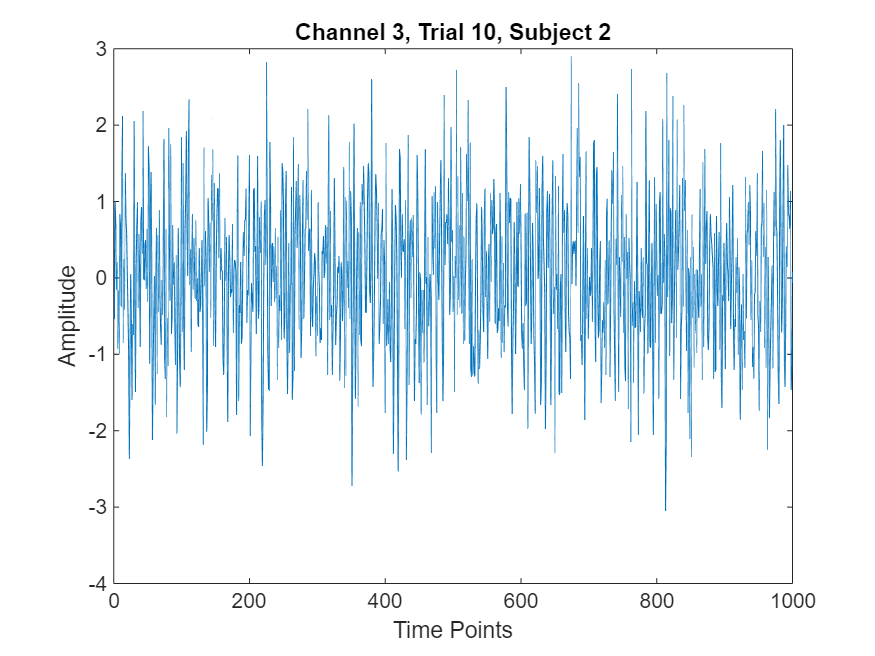


% Accessing specific data:
% Data for channel 3, all time points, trial 10, subject 2
channel3_trial10_sub2 = eegData(3, :, 10, 2);
plot(channel3_trial10_sub2);
title('Channel 3, Trial 10, Subject 2');
xlabel('Time Points'); ylabel('Amplitude');

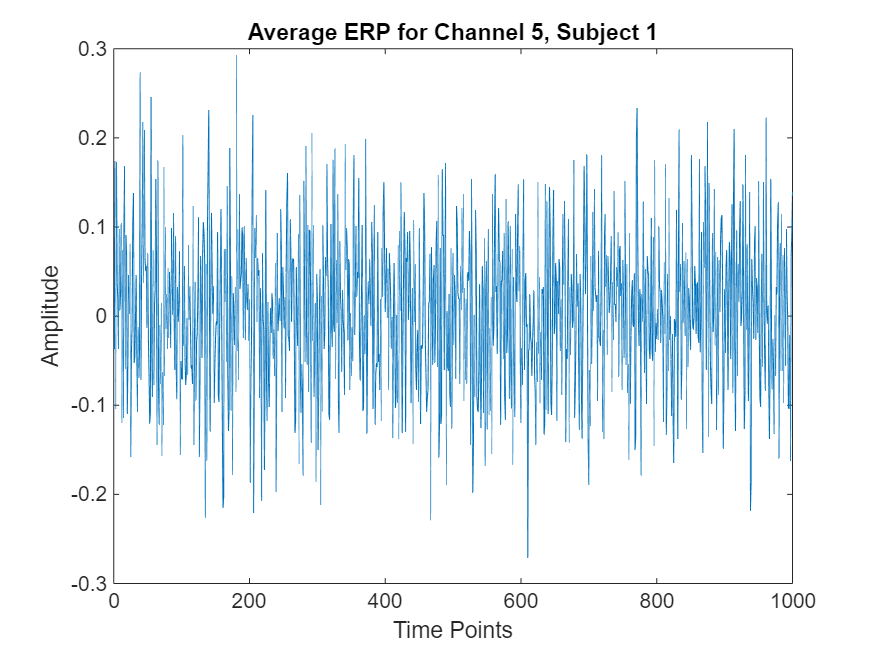


% Average across trials for a specific subject and channel
avgERP_sub1_ch5 = mean(eegData(5, :, :, 1), 3);
figure; plot(avgERP_sub1_ch5);
title('Average ERP for Channel 5, Subject 1');
xlabel('Time Points'); ylabel('Amplitude');

**Data Structures: Cell Arrays (** Flexible Containers for Heterogeneous Data)

- **Concept**: Arrays where each element (a "cell") can hold data of a *different type* or *different size*. Indexed using curly braces `{}`.

- **When to Use**:

- **Varying Lengths**: Storing trials with different numbers of time points (e.g., due to varying response times).

- **Mixed Data Types**: Holding numbers, strings, logical values, or other arrays/structs.

- **Organizing Lists**: Storing lists of file names, subject IDs, or conditions.

- **Example**: `myCell = {'Subject1.mat', [1 2 3], struct('age', 25), rand(5,5), 'Condition A'};`

trialDataCell = cell(1, numTrials);
for i = 1:numTrials
    trialDataCell{i} = randn(numChannels, randi([500, 1500])); % Simulate varying trial lengths
end
fprintf('Size of trial 1: %s\n', mat2str(size(trialDataCell{1})));

Size of trial 1: [64 1488]


fprintf('Size of trial 10: %s\n', mat2str(size(trialDataCell{10})));

Size of trial 10: [64 1104]


**Data Structures: Structures (Structs)**

- **Concept**: Data containers that group related data using *named fields*. Similar to objects or dictionaries.

- **Application**: Ideal for organizing complex neuroscience datasets and their associated metadata in a human-readable and logically structured way. Enhances code readability and data accessibility.

- **Examples**:

- **EEG Data Structure (e.g., EEGLAB's **`EEG`** struct)**:

- `EEG.data`: The actual neural signal (`channels x time x trials`).

- `EEG.srate`: Sampling rate (scalar, e.g., `250`).

- `EEG.chanlocs`: Structure array with channel location info.

- `EEG.event`: Structure array with event markers (type, latency).

- **Subject Information Array**:

- `Subject(1).ID = 'Sub001';`

- `Subject(1).Age = 22;`

- `Subject(1).Gender = 'Female';`

- `Subject(1).EEGdata = ...;` (link or actual data).

- **Image Placeholder**: A diagram showing a single structure (e.g., "EEG_Dataset"). Inside, clearly labeled fields (e.g., `data`, `srate`, `chanlocs`, `event`) each pointing to different types of data.

subject(numSubjects) = struct(); % Pre-allocate structure array

for s = 1:numSubjects
    subject(s).id = sprintf('Sub%02d', s);
    subject(s).age = randi([18, 30]);
    subject(s).gender = datasample({'Male', 'Female'}, 1);
    subject(s).eeg = randn(numChannels, numTimePoints, numTrials); % Each subject's EEG data
    subject(s).events = struct('type', {}, 'latency', {}); % Event markers
    for t = 1:numTrials
        subject(s).events(t).type = datasample({'StimA', 'StimB'}, 1);
        subject(s).events(t).latency = randi([100, numTimePoints - 100]);
    end
end

% Accessing data within a structure:
fprintf('Subject 3 ID: %s, Age: %d\n', subject(3).id, subject(3).age);

Subject 3 ID: Sub03, Age: 30


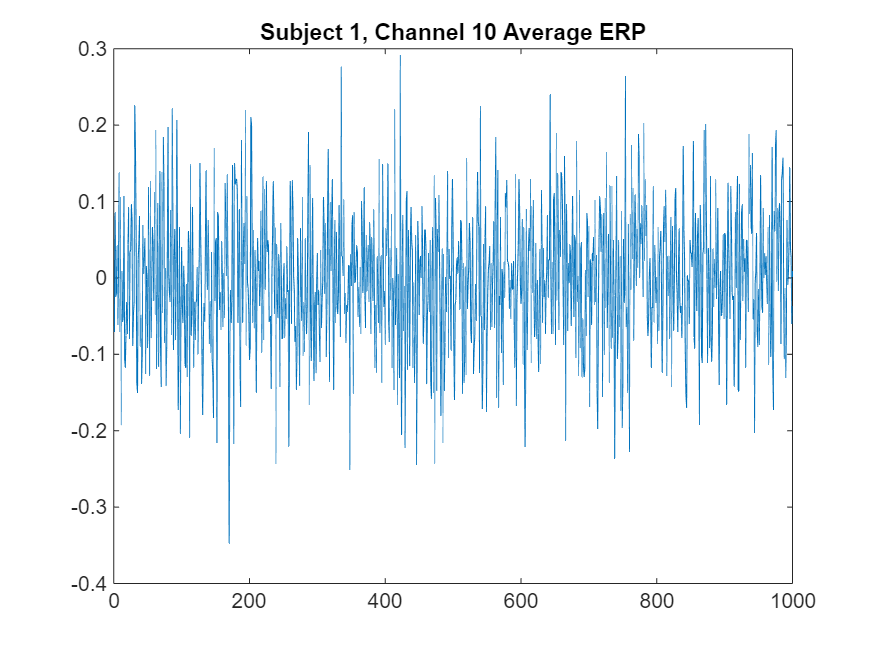

figure; plot(squeeze(mean(subject(1).eeg(10, :, :), 3)));
title('Subject 1, Channel 10 Average ERP');

**Principles of Effective Data Visualization - Why & What**

- **Exploration**: Quickly discover patterns, trends, anomalies, and relationships not obvious from raw numbers.

- **Quality Control**: Visually inspect for noise, artifacts, errors, or outliers.

- **Communication**: Present findings clearly, concisely, and compellingly to others. A good visualization conveys complex info efficiently.

- **Time Series Plots (**`plot`**)**: For raw signals, ERPs, waveforms.

- **Heatmaps (**`imagesc`**, **`pcolor`**)**: For time-frequency, connectivity matrices.

- **Histograms (**`histogram`**)**: For data distributions.

- **Topographical Maps (**`topoplot`**)**: For spatial activity on the scalp.

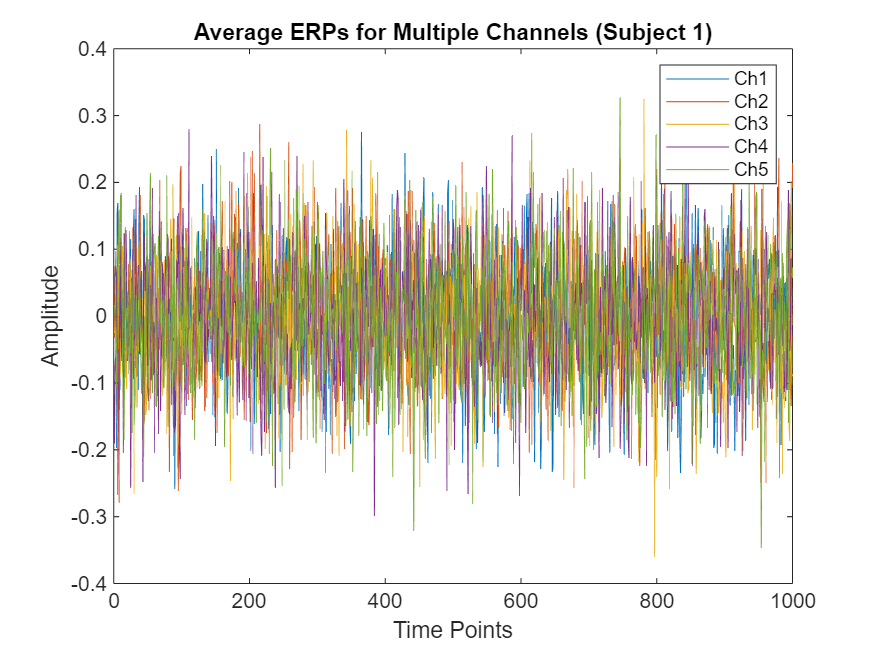

figure;
plot(squeeze(mean(subject(1).eeg(1:5, :, :), 3))'); % Plot average ERPs for first 5 channels, subject 1
legend('Ch1', 'Ch2', 'Ch3', 'Ch4', 'Ch5');
title('Average ERPs for Multiple Channels (Subject 1)');
xlabel('Time Points'); ylabel('Amplitude');

**Principles of Effective Data Visualization - Elements & Error Bars**

- **Clarity**: Easy to understand at a glance. Avoid clutter.

- **Labels and Units**: Clear axis labels with appropriate units (e.g., "Time (s)", "Amplitude (µV)").

- **Titles and Legends**: Informative titles; legends for multiple lines/categories.

- **Color Schemes**: Use perceptually uniform, accessible colormaps (e.g., `viridis`, `parula`). Avoid misleading colors.

- **Appropriate Scaling**: Choose limits that highlight data without distortion.

- **Importance of Error Bars - Quantifying Uncertainty**

- **Purpose**: Graphical representation of variability or uncertainty (e.g., around a mean). Communicates precision.

- **Types**:

- **Standard Error of the Mean (SEM)**: Precision of sample mean as population estimate.

- Formula: $$SEM = \frac{s}{\sqrt{n}}$$

- **Standard Deviation (SD)**: Spread of individual data points around mean.

- Formula: $$SD = \sqrt{\frac{1}{n-1}\sum_{i=1}^{n} (x_i - \bar{x})^2}$$

- **Interpretation**: Crucial for assessing reliability, comparing groups, and generalizability. Overlapping SEMs often suggest non-significance.

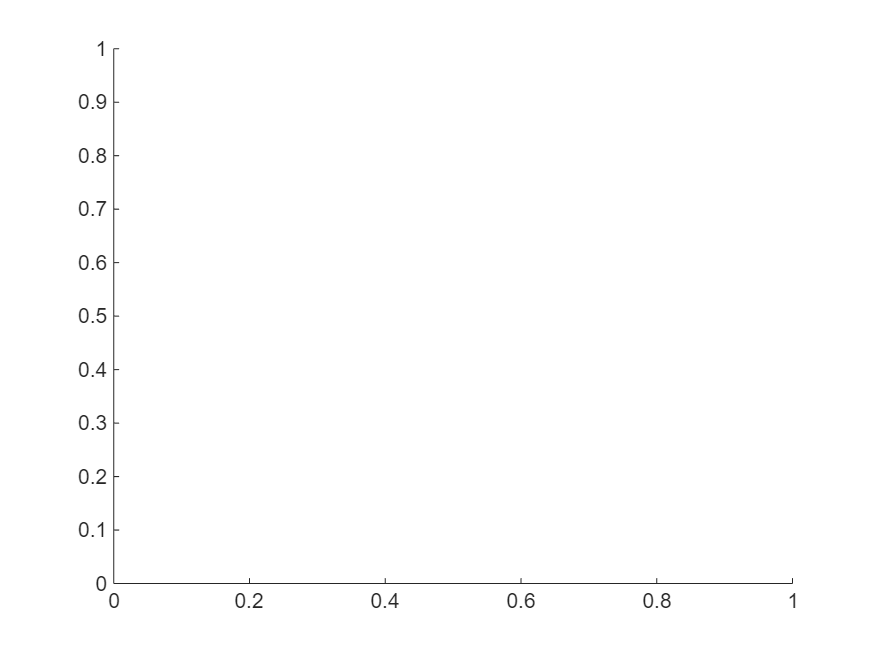

Error using shadedErrorBar (line 92)
No value was given for 'b'. Name-value pair arguments require a name followed by a value.

% Please download and put shadedErrorBar m file in your directory
meanERP_ch1_sub1 = mean(subject(1).eeg(1, 1:100, :), 3);
semERP_ch1_sub1 = std(subject(1).eeg(1, 1:100, :), [], 3) / sqrt(numTrials);

figure;
shadedErrorBar(1:100, meanERP_ch1_sub1, semERP_ch1_sub1, 'lineProps', 'b');

title('Mean ERP with SEM (Channel 1, Subject 1)');
xlabel('Time Points'); ylabel('Amplitude');

% Simulate an event at time point 200
eventTime = 200;
figure;
plot(channel3_trial10_sub2);
hold on;
plot([eventTime, eventTime], ylim, 'r--', 'LineWidth', 1.5); % Vertical line at event
text(eventTime + 10, max(ylim)*0.9, 'Event', 'Color', 'r');
hold off;
title('Channel 3, Trial 10, Subject 2 with Event Marker');
xlabel('Time Points'); ylabel('Amplitude');

% --- Custom Colormaps for Heatmaps (e.g., Time-Frequency) ---
% We'll use this more in Session 4, but a preview.
data_heatmap = randn(50, 100); % Simulate a small time-frequency map
figure;
imagesc(data_heatmap);
colorbar;
colormap(parula); % Or 'parula', 'viridis', etc.
title('Example Heatmap');
xlabel('Time'); ylabel('Frequency');

## 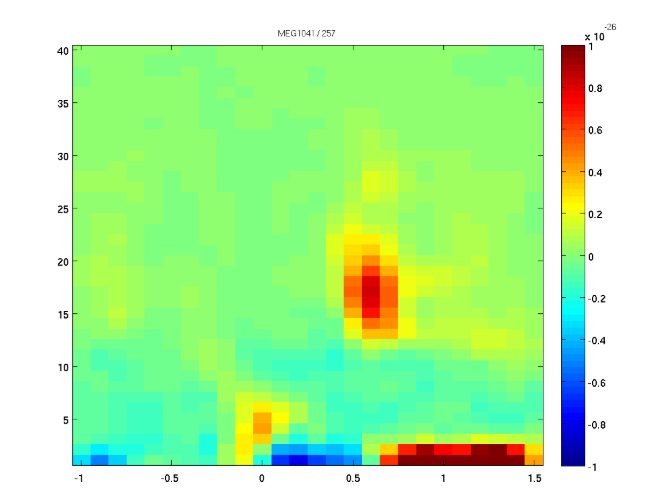

load('sampleEEGdata.mat');